# Define the spring mass system

m = 1;
k = 1;
b = 1;

A = [0 1;
    -k/m -b/m]

A =      0     1
    -1    -1


B = [0 0;
     1 1];
C = [1 0];
D = [0 0];

## Define model

plant = ss(A, B, C, D)

plant =
 
  A = 
       x1  x2
   x1   0   1
   x2  -1  -1
 
  B = 
       u1  u2
   x1   0   0
   x2   1   1
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1  u2
   y1   0   0
 
Continuous-time state-space model.



size(plant)

State-space model with 1 outputs, 2 inputs, and 2 states.


plant.InputName = {'f','f_d'}

plant =
 
  A = 
       x1  x2
   x1   0   1
   x2  -1  -1
 
  B = 
         f  f_d
   x1    0    0
   x2    1    1
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
         f  f_d
   y1    0    0
 
Continuous-time state-space model.



plant.InputUnit = {'N', 'N'}

plant =
 
  A = 
       x1  x2
   x1   0   1
   x2  -1  -1
 
  B = 
         f  f_d
   x1    0    0
   x2    1    1
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
         f  f_d
   y1    0    0
 
Continuous-time state-space model.



plant.StateName = {'x', 'x_dot'}

plant =
 
  A = 
              x  x_dot
   x          0      1
   x_dot     -1     -1
 
  B = 
            f  f_d
   x        0    0
   x_dot    1    1
 
  C = 
           x  x_dot
   y1      1      0
 
  D = 
         f  f_d
   y1    0    0
 
Continuous-time state-space model.



plant.StateUnit = {'m', 'm/s'}

plant =
 
  A = 
              x  x_dot
   x          0      1
   x_dot     -1     -1
 
  B = 
            f  f_d
   x        0    0
   x_dot    1    1
 
  C = 
           x  x_dot
   y1      1      0
 
  D = 
         f  f_d
   y1    0    0
 
Continuous-time state-space model.



plant.OutputName = {'x'}

plant =
 
  A = 
              x  x_dot
   x          0      1
   x_dot     -1     -1
 
  B = 
            f  f_d
   x        0    0
   x_dot    1    1
 
  C = 
          x  x_dot
   x      1      0
 
  D = 
        f  f_d
   x    0    0
 
Continuous-time state-space model.



plant.OutputUnit = {'m'}

plant =
 
  A = 
              x  x_dot
   x          0      1
   x_dot     -1     -1
 
  B = 
            f  f_d
   x        0    0
   x_dot    1    1
 
  C = 
          x  x_dot
   x      1      0
 
  D = 
        f  f_d
   x    0    0
 
Continuous-time state-space model.



damp(plant)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -5.00e-01 + 8.66e-01i     5.00e-01       1.00e+00         2.00e+00    
 -5.00e-01 - 8.66e-01i     5.00e-01       1.00e+00         2.00e+00    


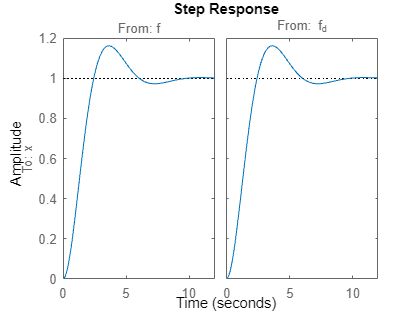

step(plant)

## Set MPC Signals

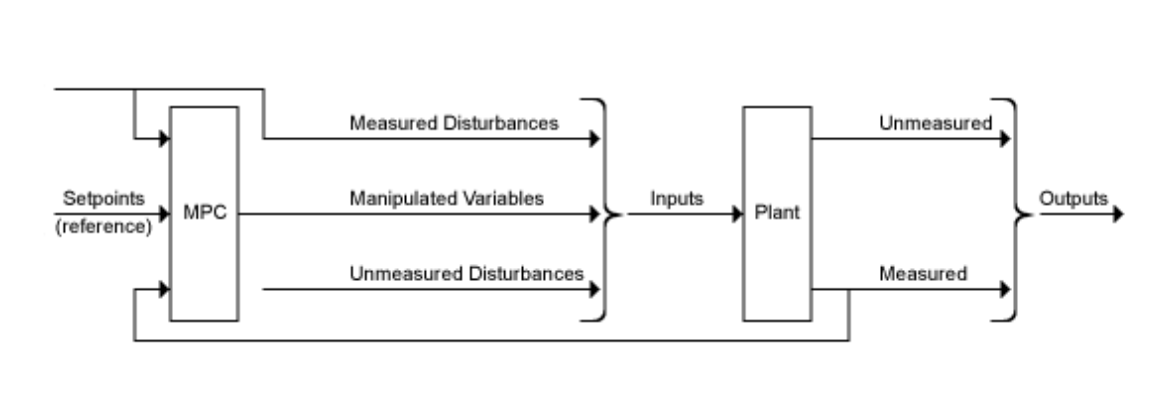

% set the signals 
plant = setmpcsignals(plant,'MV',1,'UD',2,'MO',1)

plant =
 
  A = 
              x  x_dot
   x          0      1
   x_dot     -1     -1
 
  B = 
            f  f_d
   x        0    0
   x_dot    1    1
 
  C = 
          x  x_dot
   x      1      0
 
  D = 
        f  f_d
   x    0    0
 
Input groups:              
       Name        Channels
    Manipulated       1    
    Unmeasured        2    
                           
Output groups:          
      Name      Channels
    Measured       1    
                        
Continuous-time state-space model.



% make the mpc model
dt = 0.01;
mpcobj = mpc(plant,dt)

-->The "PredictionHorizon" property is empty. Assuming default 10.
-->The "ControlHorizon" property is empty. Assuming default 2.
-->The "Weights.ManipulatedVariables" property is empty. Assuming default 0.00000.
-->The "Weights.ManipulatedVariablesRate" property is empty. Assuming default 0.10000.
-->The "Weights.OutputVariables" property is empty. Assuming default 1.00000.
 
MPC object (created on 12-May-2023 15:19:13):
---------------------------------------------
Sampling time:      0.01 (seconds)
Prediction Horizon: 10
Control Horizon:    2

Plant Model:        
                                      --------------
      1  manipulated variable(s)   -->|  2 states  |
                                      |            |-->  1 measured output(s)
      0  measured disturbance(s)   -->|  2 inputs  |
                                      |            |-->  0 unmeasured output(s)
      1  unmeasured disturbance(s) -->|  1 outputs |
                                      --------------
Ind

disturbance_model = getindist(mpcobj)

-->Converting model to discrete time.
-->The "Model.Disturbance" property is empty:
   Assuming unmeasured input disturbance #2 is integrated white noise.
   Assuming no disturbance added to measured output channel #1.
-->The "Model.Noise" property is empty. Assuming white noise on each measured output.

disturbance_model =
 
  A = 
       x1
   x1   1
 
  B = 
       f_d-wn
   x1    0.01
 
  C = 
        x1
   f_d   1
 
  D = 
        f_d-wn
   f_d       0
 
Sample time: 0.01 seconds
Discrete-time state-space model.



mpcobj.Model.Disturbance = tf(4,[1 0])

 
MPC object (created on 12-May-2023 15:19:13):
---------------------------------------------
Sampling time:      0.01 (seconds)
Prediction Horizon: 10
Control Horizon:    2

Plant Model:        
                                      --------------
      1  manipulated variable(s)   -->|  2 states  |
                                      |            |-->  1 measured output(s)
      0  measured disturbance(s)   -->|  2 inputs  |
                                      |            |-->  0 unmeasured output(s)
      1  unmeasured disturbance(s) -->|  1 outputs |
                                      --------------
Indices:
  (input vector)    Manipulated variables: [1 ]
                  Unmeasured disturbances: [2 ]
  (output vector)        Measured outputs: [1 ]

Disturbance and Noise Models:
        Output disturbance model: default (type "getoutdist(mpcobj)" for details)
         Input disturbance model: user specified (type "getindist(mpcobj)" for more details)
         Measurement n

disturbance_model = getindist(mpcobj)

disturbance_model =
 
  A = 
       x1
   x1   1
 
  B = 
       Noise#1
   x1     0.02
 
  C = 
        x1
   f_d   2
 
  D = 
        Noise#1
   f_d        0
 
Sample time: 0.01 seconds
Discrete-time state-space model.

